disp('============IDENTIFICAÇÃO CONVERSOR BUCK (simulik)============');

============IDENTIFICAÇÃO CONVERSOR BUCK (simulik)============


disp('Dados ensaio: 20KHz ; Ts = 50us');

Dados ensaio: 20KHz ; Ts = 50us


disp('Laboratorio LINCE');

Laboratorio LINCE


disp('Discente: Luiz Felipe Souza de Lima Silva');

Discente: Luiz Felipe Souza de Lima Silva


1. Inicialização e declaração de parametros:

clear, clc, close all

disp('------------------------------------------------------');

------------------------------------------------------


disp('PARAMETROS DE PROJETO:');

PARAMETROS DE PROJETO:



Fs = 20000

Fs = 20000

Ts = 5.0e-5

Ts = 5.0000e-05

d =  0.3

d = 0.3000

Vs = 30

Vs = 30

C = 0.000041666667

C = 4.1667e-05

L = 0.000470

L = 4.7000e-04

R = 10.0

R = 10

num = Vs/(C*L);
den = [1,1/(C*R) , 1/(C*L)];
Gs = tf(num,den);


2. Função de transferencia matematica:

disp('------------------------------------------------------');

------------------------------------------------------


disp('FUNÇÃO DE TRANSFERENCIA MODELADA ANALITICAMENTE:');

FUNÇÃO DE TRANSFERENCIA MODELADA ANALITICAMENTE:



Gs = tf(num,den)

Gs =
 
         1.532e09
  -----------------------
  s^2 + 2400 s + 5.106e07
 
Continuous-time transfer function.
Model Properties



disp('Polos e zeros:');

Polos e zeros:



pole(Gs)

ans = 1.0e+03 *

  -1.2000 + 7.0444i
  -1.2000 - 7.0444i




disp('Resposta ao Degrau:');

Resposta ao Degrau:


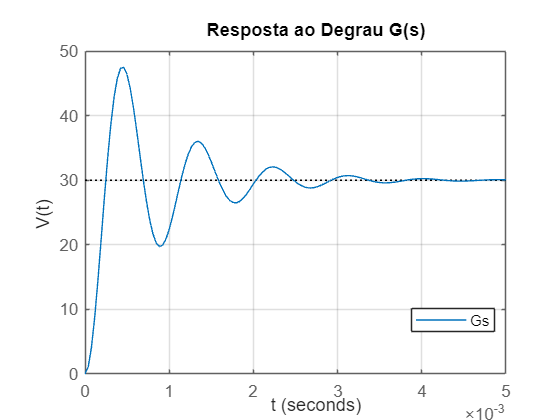


figure(1)
step(Gs)
xlabel('t'); ylabel('V(t)');
grid on; legend('Location', 'best');
title('Resposta ao Degrau G(s)') 


disp('Discretização de G(s) utilizando método "matched":');

Discretização de G(s) utilizando método "matched":


Gz = c2d(Gs, Ts ,'matched')

Gz =
 
     1.785 z + 1.785
  ----------------------
  z^2 - 1.768 z + 0.8869
 
Sample time: 5e-05 seconds
Discrete-time transfer function.
Model Properties


disp('------------------------------------------------------');

------------------------------------------------------


3. Importação dos dados Gerados via Simulink:

%% Importação dos dados de saída e entrada (simulink)
load("DataIdent.mat")
Nd = 200;
t = DadosBuck(1,1:end-Nd);
u = DadosBuck(2,Nd:end-1);
v = DadosBuck(3,Nd:end-1);

3. Coleta de dados e Identificação:

%% Eliminação da componente DC do sistema
mu_u = mean(u);
mu_v = mean(v);

u = u - mu_u;
v = v - mu_v;
y = transpose(v);

disp('IDENTIFICAÇÃO:');

IDENTIFICAÇÃO:


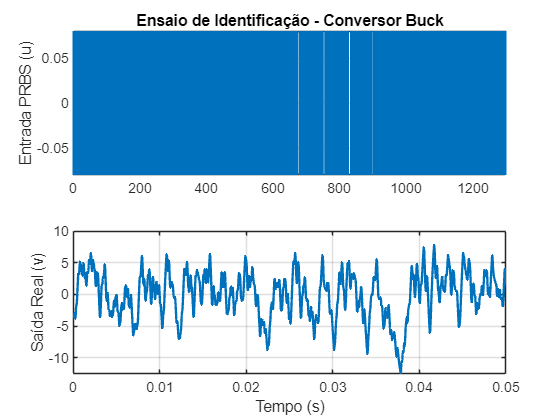

%% relação gráfica de saída e entrada
figure(2);
clf; % Limpa a figura 2 e reseta os eixos
subplot(2,1,1);
stairs(1:length(u), u, 'LineWidth', 1.4);
ylabel('Entrada PRBS (u)');
title('Ensaio de Identificação - Conversor Buck');
xlim([0 1300]);   
ylim([-0.08 0.08]); 
grid on;

subplot(2,1,2);
plot(t(1:length(v)), v, 'LineWidth', 1.4);
ylabel('Saída Real (v)');
xlabel('Tempo (s)');
xlim([0 0.05]);   

grid on;   



%% Construção matricial - regressores
Ns = numel(t);

M = zeros(Ns-3,4);

for n = 3:Ns
    phi = [y(n-1), y(n-2), u(n-1), u(n-2)];
    M(n, :) = phi;
end

theta = M\y;
a1 = theta(1);
a2 = theta(2);
b1 = theta(3);
b2 = theta(4);
ys = zeros(size(y));
ys(1:2) = y(1:2);

yp = M * theta;

disp('MODELO ARX OBTIDO:');

MODELO ARX OBTIDO:


Be = [0, b1, b2];
Ae = [1, -a1, -a2];
Gze = tf(Be, Ae, Ts)

Gze =
 
     1.378 z + 0.9447
  ----------------------
  z^2 - 1.226 z + 0.3007
 
Sample time: 5e-05 seconds
Discrete-time transfer function.
Model Properties


disp('------------------------------------------------------');

------------------------------------------------------


4. Analise e comparação de modelos:

%% Comparação ARX VS saída do sistema.
disp('ANALISE E COMPARAÇÃO DE MODELOS:');

ANALISE E COMPARAÇÃO DE MODELOS:


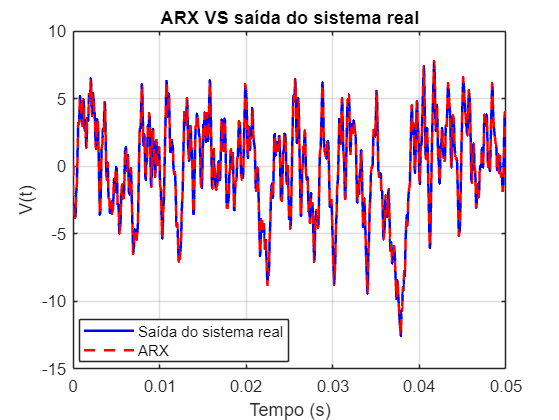

figure(3);
clf; % Garante uma nova janela limpa
% 'b--' cria a linha tracejada azul para a saída real
plot(t, y, 'b', 'LineWidth', 1.5)
hold on
% 'r--' cria a linha tracejada vermelha para o modelo ARX
plot(t, yp, 'r--', 'LineWidth', 1.5)

legend('Saída do sistema real', 'ARX', 'Location', 'best');
hold off
grid on
xlabel('Tempo (s)');
ylabel('V(t)');
title('ARX VS saída do sistema real');
xlim([0 0.05]);    %maximo de 50us

%ylim([-1.5 2]); 

disp('Funções de transferencia:');

Funções de transferencia:


disp('Gz modelo analitico');

Gz modelo analitico


Gz

Gz =
 
     1.785 z + 1.785
  ----------------------
  z^2 - 1.768 z + 0.8869
 
Sample time: 5e-05 seconds
Discrete-time transfer function.
Model Properties



disp('Gze modelo estimado');

Gze modelo estimado



Gze

Gze =
 
     1.378 z + 0.9447
  ----------------------
  z^2 - 1.226 z + 0.3007
 
Sample time: 5e-05 seconds
Discrete-time transfer function.
Model Properties


disp('------------------------------------------------------');

------------------------------------------------------



disp('GRÁFICO DE COERÊNCIA (PRBS vs Saída RealARX)');

GRÁFICO DE COERÊNCIA (PRBS vs Saída RealARX)


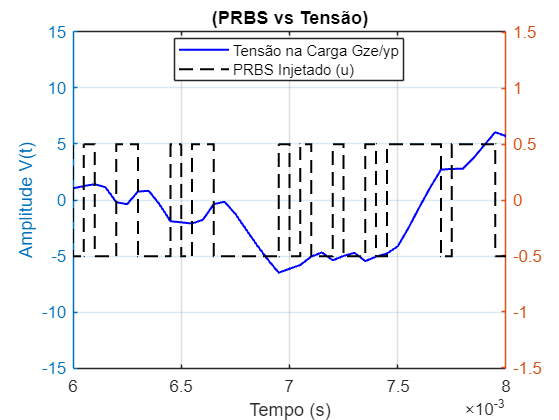


figure(7)
clf;
yyaxis left
plot(t, yp, 'b', 'LineWidth', 1.2) 
ylabel('Amplitude V(t)');
ylim([-max(abs(y))*1.2, max(abs(y))*1.2]); 
xlim([0.006 0.008]); 

yyaxis right
stairs(t, u, 'Color', 'k', 'LineStyle', '--', 'LineWidth', 1.2)
ylim([-max(abs(u))*3, max(abs(u))*3]); 
xlim([0.006 0.008]); 

xlabel('Tempo (s)');
title('(PRBS vs Tensão)');
grid on;

legend('Tensão na Carga Gze/yp', 'PRBS Injetado (u)', 'Location', 'best');


disp('------------------------------------------------------');

------------------------------------------------------



disp('GRÁFICO DE COERÊNCIA (Saída Real, ARX e PRBS)');

GRÁFICO DE COERÊNCIA (Saída Real, ARX e PRBS)


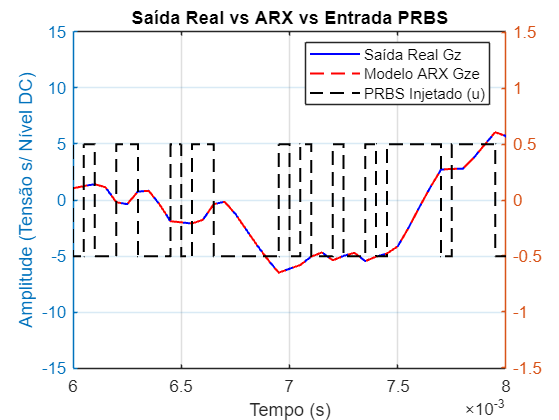


figure(6)
clf;

yyaxis left
plot(t, y, 'b', 'LineWidth', 1.2) 
hold on
plot(t, yp, 'r--', 'LineWidth', 1.2) 
ylabel('Amplitude (Tensão s/ Nível DC)');
ylim([-max(abs(y))*1.2, max(abs(y))*1.2]); 
xlim([0.006 0.008]); 

hold off

yyaxis right
stairs(t, u, 'Color', 'k', 'LineStyle', '--', 'LineWidth', 1.2)
ylim([-max(abs(u))*3, max(abs(u))*3]); 
xlim([0.006 0.008]); 

xlabel('Tempo (s)');
title('Saída Real vs ARX vs Entrada PRBS');
grid on;

legend('Saída Real Gz', 'Modelo ARX Gze', 'PRBS Injetado (u)', 'Location', 'best');

disp('------------------------------------------------------');

------------------------------------------------------


5.Ajuste R2:

%% Ajuste
disp('AJUSTE R2:');

AJUSTE R2:


R2 = 1 - sum((y - yp).^2)/sum((y - mean(y)).^2)

R2 = 0.9983

disp('------------------------------------------------------');

------------------------------------------------------


6. Analise de polos e zeros:

disp('ANALISE DE POLOS E ZEROS:');

ANALISE DE POLOS E ZEROS:



disp('BLUE - GZ');

BLUE - GZ


disp('RED - GZe');

RED - GZe


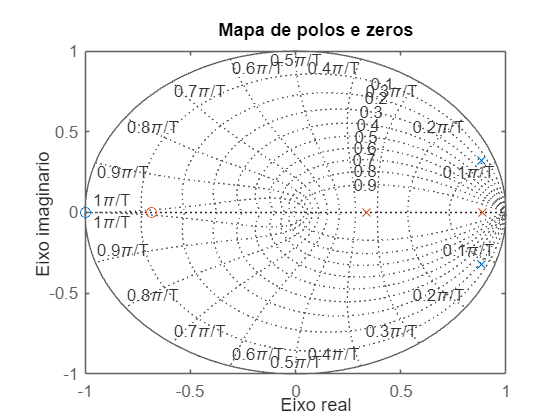


figure(5)
clf;
pzmap(Gz)
zgrid
hold on

pzmap(Gze)
hold off

xlabel('Eixo real');
ylabel('Eixo imaginario');
title('Mapa de polos e zeros');

disp('------------------------------------------------------');

------------------------------------------------------


7. Resposta ao degrau:

disp('resposta ao degrau Modelo discreto analitico');

resposta ao degrau Modelo discreto analitico


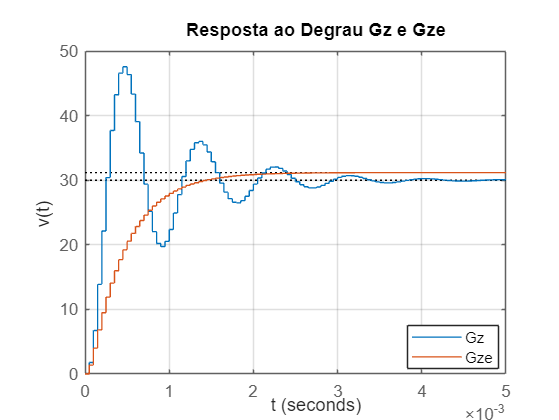

figure(6)
clf;
step(Gz, Gze)
xlabel('t'); ylabel('v(t)');
grid on; 
legend('Gz', 'Gze', 'Location', 'best');
title('Resposta ao Degrau Gz e Gze');

8. Diagrama de Bode:

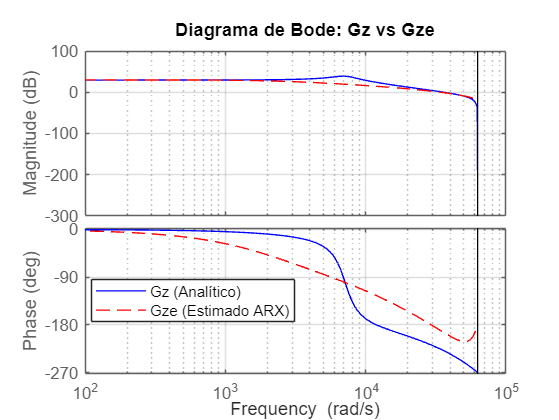

figure(7);
clf;
bode(Gz, 'b', Gze, 'r--');
grid on;
legend('Gz (Analítico)', 'Gze (Estimado ARX)', 'Location', 'best');
title('Diagrama de Bode: Gz vs Gze');

9. Projeto dos controladores: